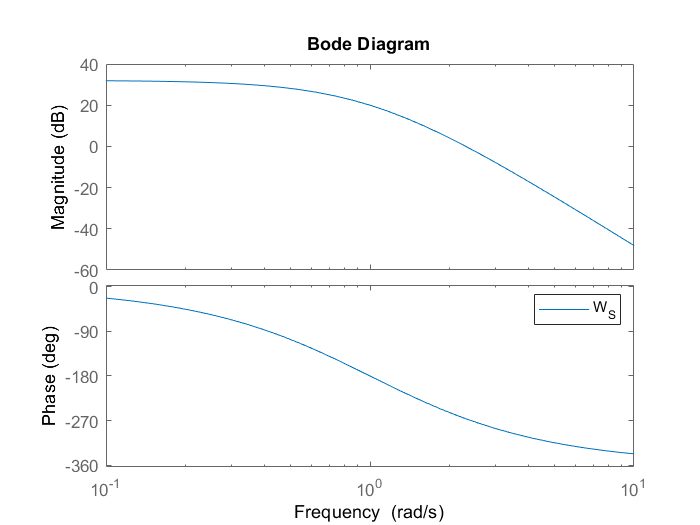

clear all;
s = tf('s');
P = 1/(s + 1)/s;

W_T = (s + 1)/(0.01*s + 1)/10;

% Eroare de cel mult 10% la referinte sinusoidale din
% banda de frecvente [0, 1] rad/s

% k = 80 si puterea 16 works fine

k = 10 * sqrt(16);
W_S = k/(s + 1)^4;
% W_S = k *s/s;

figure;
bode(W_S);
legend('W_S');

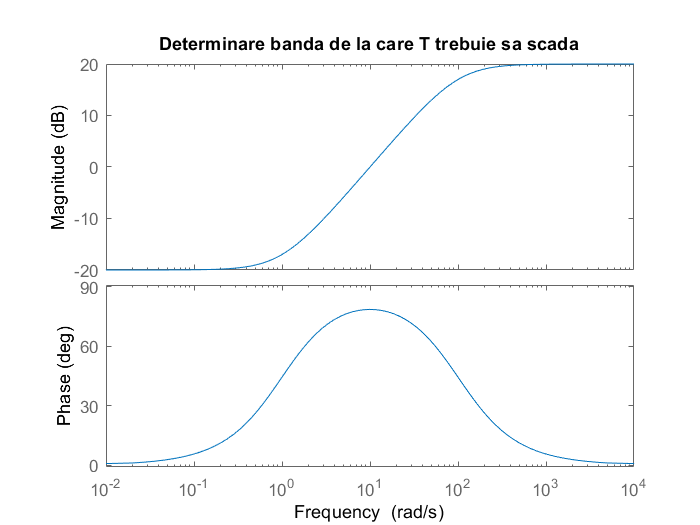


% Din enunt rezulta banda de performanta [0, 1], iar uitandu-ne
% la forma lui W_T putem sa determina pulsatia de la care T incepe
% sa scada
% C = 35 * 29 / 6 * (s + 6)/(s + 29);
C = 20 * 29 / 4 * (s + 4)/(s + 29);

% C = 25 * 29 / 2.15 * (s + 2.15) / (s + 29);
% C = 14;
L = P * C;

bode(W_T);
title('Determinare banda de la care T trebuie sa scada');

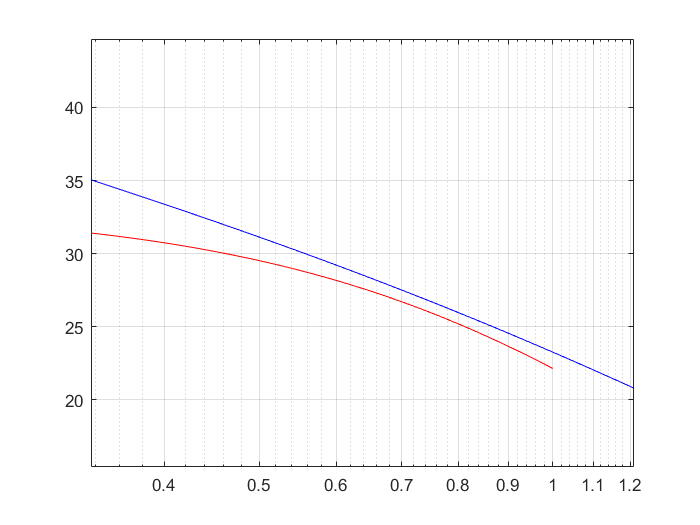

% Din grafic => w_BT = 13 rad/s

% Calcularea restrictiilor
omeg_jf = logspace(-4, 0, 1000);
omeg_if = logspace(1.12, 4, 1000);

omeg_L = logspace(-4, 4, 10000);
[R_if, R_jf] = calculRestrictii(W_S, W_T, omeg_jf, omeg_if);

amp_L = bode(L, omeg_L);
amp_L = amp_L(:);
figure;

semilogx(omeg_jf, 20*log10(R_jf), 'r', ...
    omeg_L, 20*log10(amp_L), 'b', ...
    omeg_if, 20*log10(R_if), 'r');
grid on;

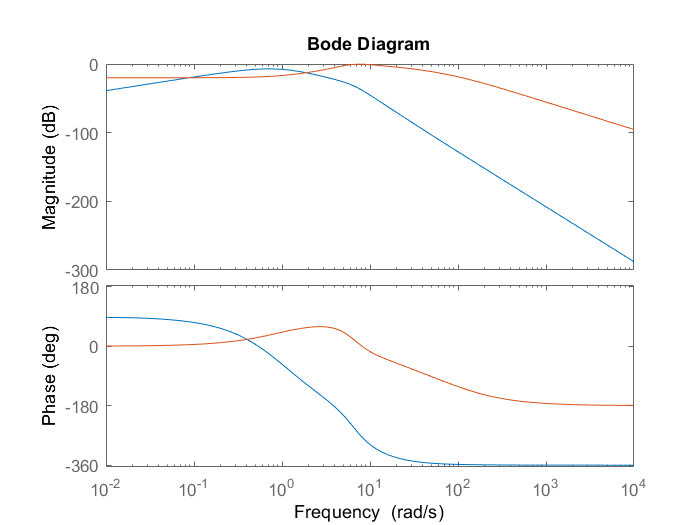



S = 1/(1 + L);
T = L/(1 + L);


figure;
bode(W_S * S);
hold on;
bode(W_T * T);
hold off;

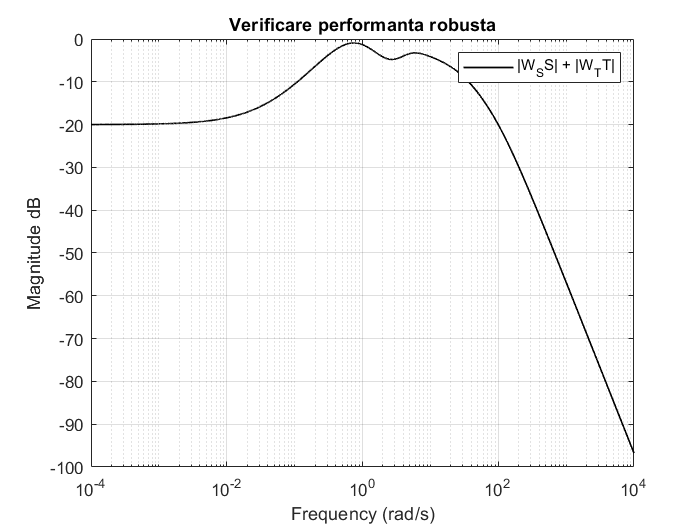


plotPerfRobs(L, omeg_L, W_S, W_T);

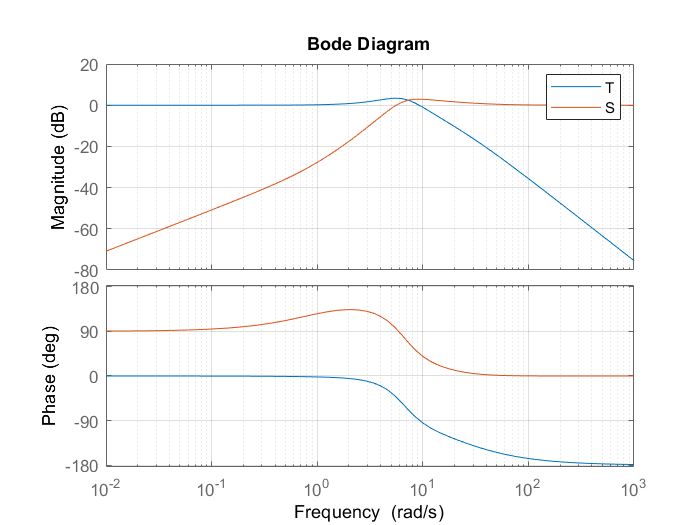


figure;
bode(T);
hold on;
grid on;
bode(S);
legend('T', 'S');
hold off;


% Verificare eliminare zgomot

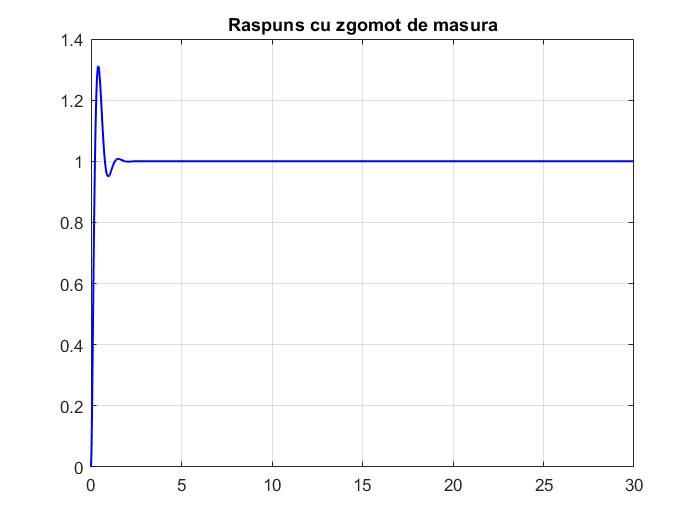


w = 1e5;
Time = 30;
Ts = 1/(4 * w);
t = 0 : Ts : Time;
reference = ones(1, numel(t));
A = 0.25;
noise = A * sin(2*pi*w * t);

y_out = lsim(T, reference - noise, t);

figure;

grid on;
plot(t, y_out, 'Color', 'b', 'LineWidth', 1.2);
title('Raspuns cu zgomot de masura');
grid on;

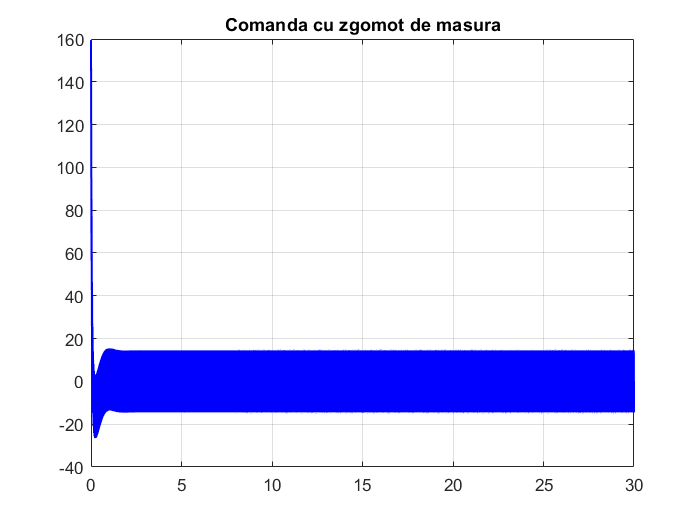

% Vizualizare comanda

w = 1e5;
Time = 30;
Ts = 1/(4 * w);
t = 0 : Ts : Time;
reference = ones(1, numel(t));
A = 0.1;
noise = A * sin(2*pi*w * t);

y_out = lsim(C/(1+P*C), reference - noise, t);

figure;

grid on;
plot(t, y_out, 'Color', 'b', 'LineWidth', 1.2);
title('Comanda cu zgomot de masura');
grid on;

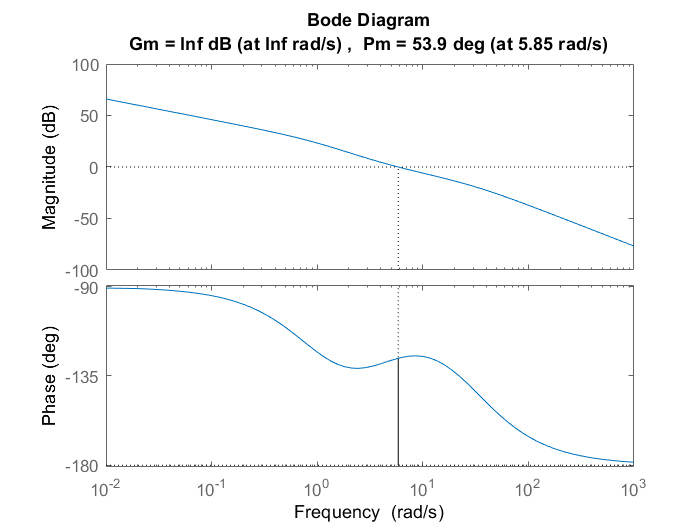

margin(L)

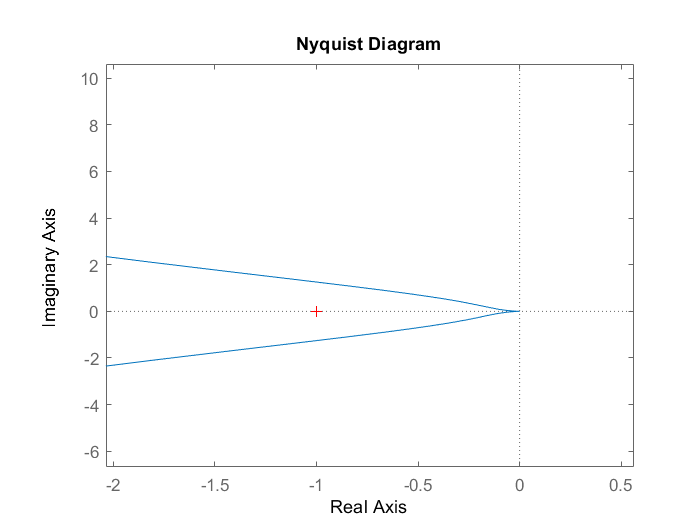

nyquist(L)